# Lab 8

**Francesca Bennett**

**Collborators: Taylor Prewitt, Natalie Shen**

**Part 1**

clear all; close all; clc

%Higgs Data
h5disp("higgs_100000_pt_250_500.h5");

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


Higgs = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');

h5disp("qcd_100000_pt_250_500.h5");

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcd = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

Plot Observed Data for High Luminosity

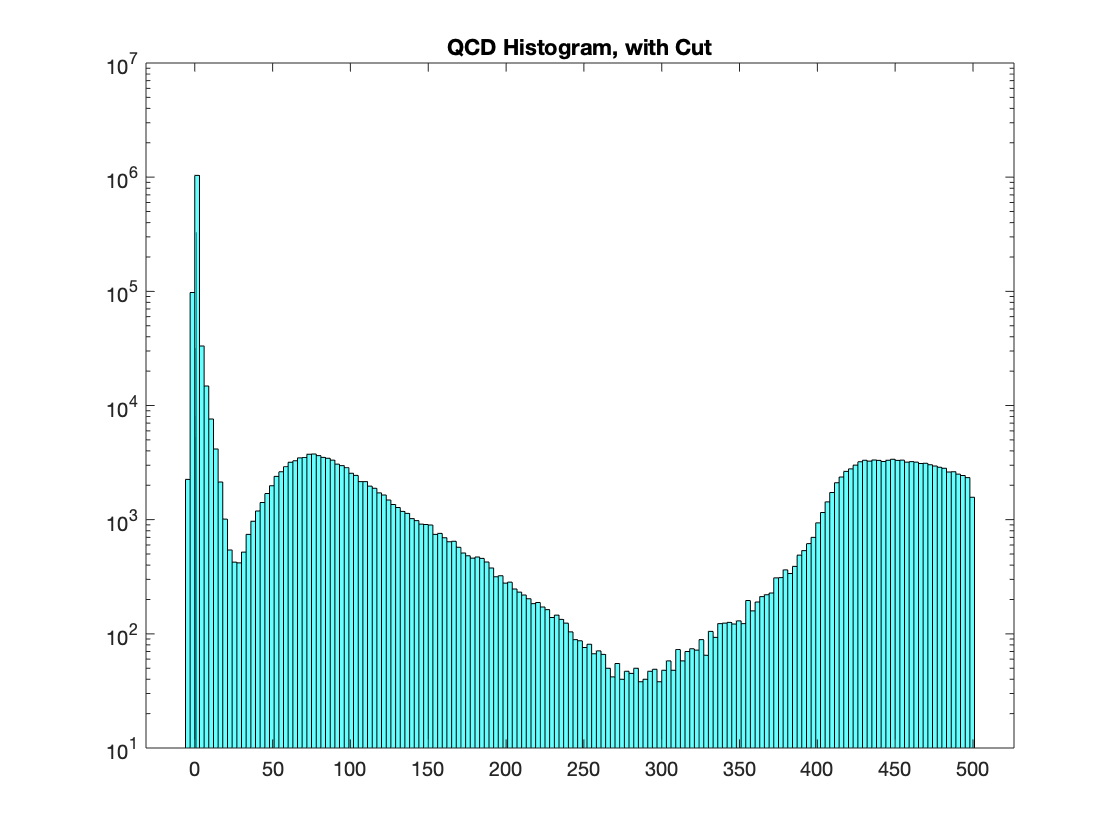

UpperQ=cdf('Poisson',1,qcd);

histogram(UpperQ,'FaceColor','blue')
title('QCD Histogram, with Cut')
set(gca,'Yscale','log')
hold on
histogram(qcd,'FaceColor','cyan')
hold off

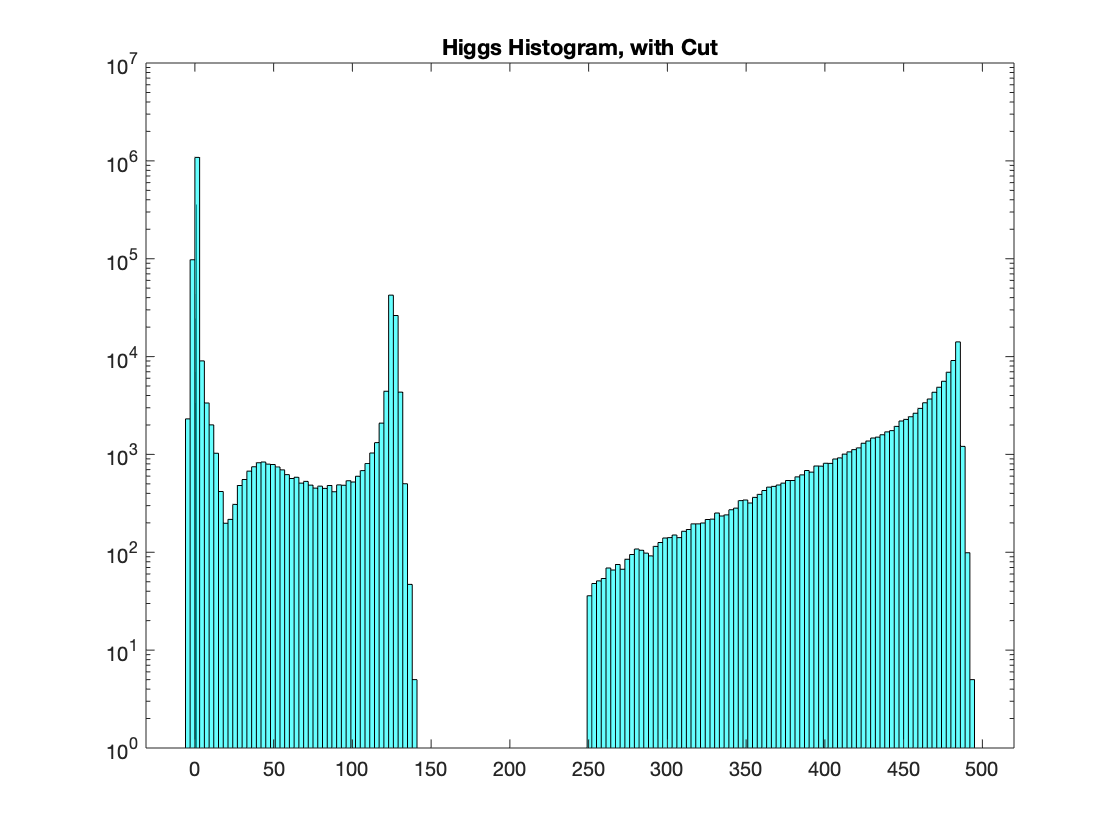



UpperH=cdf('Poisson',1,Higgs);
histogram(UpperH,'FaceColor','blue')
set(gca,'Yscale','log')
title('Higgs Histogram, with Cut')
hold on
histogram(Higgs,'FaceColor','cyan')
hold off